# Elliptic Equation - Laplace (Finite Difference approach) and `Dictionaries`

In this example we'll solve a partial differential equation for a **2D Steady State heat conduction** problem.  We'll solve this problem using 2 different approaches  

- via the PDE toolbox 

- via A Finite Difference approach - which we'll develop from scratch

 **So what's the "new" thing that we'll review in this example ?**

With the Finite Difference approach:

- We'll use a data container called a [`dictionary`](matlab:  web(fullfile(docroot, 'matlab/ref/dictionary.html')))  as our mechanism to **"Look up" **information about our nodes - this makes formulating a solution **soooo easy !**

- A [`dictionary`](matlab:  web(fullfile(docroot, 'matlab/ref/dictionary.html'))) performs data "lookup" much ... **much faster** than a table.

- We'll utilise the [`sparse`](matlab:  web(fullfile(docroot, 'matlab/ref/sparse.html'))) matrices to efficiently represent and solve a matrix problem of the form $A\ldotp x=b$

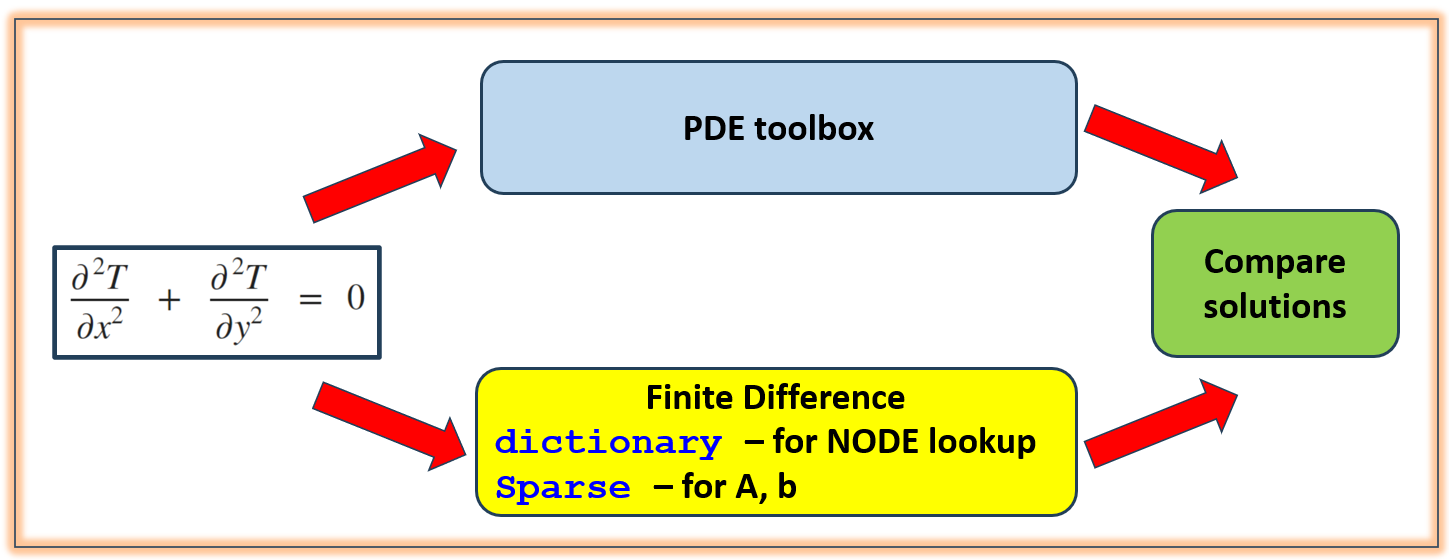

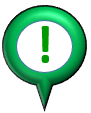**NOTE:  **

- In the solution described in [`bh_solution_LARGE_scale_using_table_LOOKUP.mlx`](matlab:  edit bh_solution_LARGE_scale_using_table_LOOKUP.mlx) we used a [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html'))) container as our mechanism to look up information about our nodes. And tables are GOOD !! ..... but when we have a table **with millions of rows**, it takes a little bit of time to find the row and then extract the data of interest. 

- An alternate data container called a [`dictionary`](matlab:  web(fullfile(docroot, 'matlab/ref/dictionary.html'))) is actually faster(much faster) when you have millions of nodes to query.

- The [`dictionary`](matlab:  web(fullfile(docroot, 'matlab/ref/dictionary.html'))) data container was first introduced in R2022b and more functionality is being added in every MATLAB Release.

- The code in this example was developed and tested in **R2024a**

## The system to be studied:

Consider the following pde - it represents the partial differential equation for a 2D **Steady State** heat conduction problem

- 
$$\frac{\partial^{\;2} T}{\partial x^2 }\;\;+\;\;\frac{\partial^{\;2} T}{\partial y^2 }\;\;=\;\;0$$


We'll consider the domain and Boundary conditions listed below - it is a square plate with side length $W$

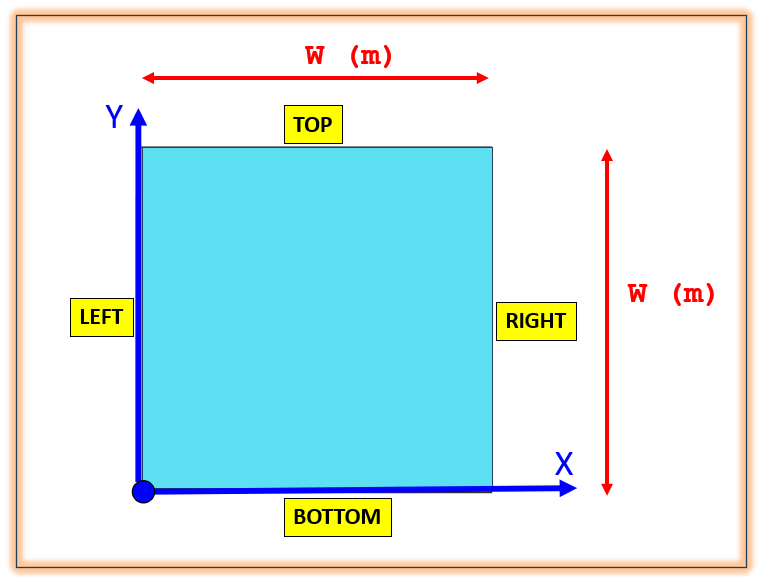

**DOMAIN:**

-     square plate $\left(0\le x\le W\right)$ and $\left(0\le y\le W\right)$

**BOUNDARY Conditions:**

- $\frac{\partial T}{\partial x}=0$  for $x=0\;\;\;\Longrightarrow$   **LEFT** Edge

- $\frac{\partial T}{\partial y}=0$  for $y=0\;\;\;\Longrightarrow$   **BOTTOM** Edge 

- $T=2\ldotp \left|x-0\ldotp 5\right|\;\;\;\;\;\;\;\Longrightarrow \;\;\;$**TOP** Edge 

- $T=y\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow$   **RIGHT** Edge 

## **Clear your workspace**

Start with a clean slate and delete any variables in your MATLAB workspace

clear

# **PDE Toolbox approach:**

First we'll solve this problem using the [**Partial Differential Equation Toolbox**](matlab:  web(fullfile(docroot, 'pde/index.html'))) for MATLAB.  The following DOC pages are worth reviewing

- [`createpde()`](matlab:  web(fullfile(docroot, 'pde/ug/createpde.html'))) : create a PDE model

- [`decsg()`](matlab:  web(fullfile(docroot, 'pde/ug/decsg.html')))** : **Decompose constructive solid 2-D geometry into minimal regions

- [`geometryFromEdges()`](matlab:  web(fullfile(docroot, 'pde/ug/pde.pdemodel.geometryfromedges.html')))  :  Create 2-D geometry from decomposed geometry matrix

- **TIP:**  study [**THIS**](matlab:  web(fullfile(docroot, 'pde/ug/constant-boundary-condition-specifications.html'))) shipping example for tips on using decsg()

## **Define the square's geometry**

In this example, we're considering a square plate with side length $W$

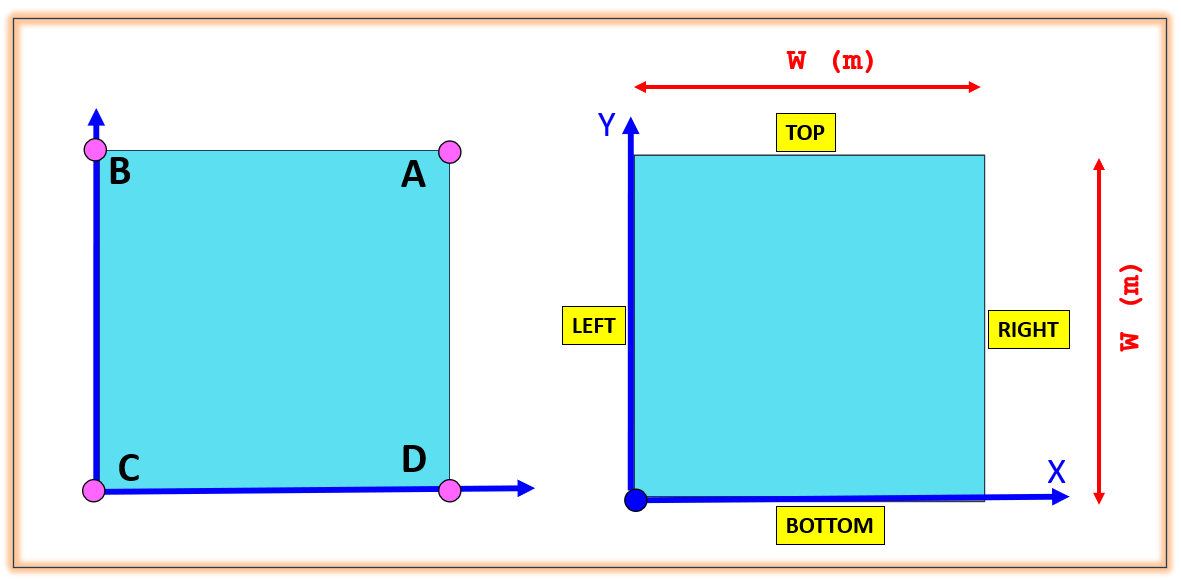

PLATE_WIDTH    = 1;               % dimension of the plate

Define the $\left(x,y\right)$ co-ordinates of the vertices of the square plate - see [`decsg()`](matlab:  web(fullfile(docroot, 'pde/ug/decsg.html')))

 **NOTE:  **specifying the verticies in the order $A\longrightarrow B\longrightarrow C\longrightarrow D$ will produce a geometry model with the following EDGES:

- TOP edge $\longrightarrow \textrm{E1}$

- LEFT edge $\longrightarrow \textrm{E2}$

- BOTTOM edge $\longrightarrow \textrm{E3}$

- RIGHT edge $\longrightarrow \textrm{E4}$

              %  A             B             C   D
R1    = [3,4,    PLATE_WIDTH,  0,            0,  PLATE_WIDTH,  ....
                 PLATE_WIDTH,  PLATE_WIDTH,  0,  0]' ;

g     = decsg(R1);

### Create the PDE model

model = createpde;

geometryFromEdges(model, g);

### Plot the domain ... and see the edge labels

NOTE the edge labels assigned to the square - we'll need these edge labels when we define the boundary conditions

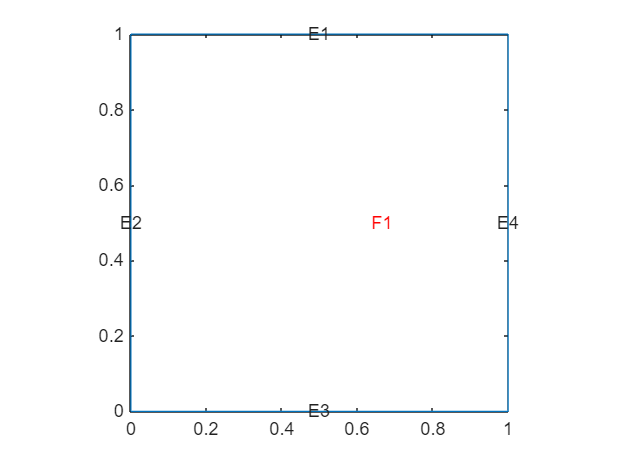

figure;
    pdegplot(model,'EdgeLabels','on','SubdomainLabels','on')
        axis equal   

## Set the Boundary conditions

- $\frac{\partial T}{\partial x}=0$  for $x=0\;\;\textrm{and}\;0<y<W\;\;\Longrightarrow$   Edge **E2  (LEFT)**

- $\frac{\partial T}{\partial y}=0$  for $y=0\;\;\textrm{and}\;0<x<W\;\;\Longrightarrow$   Edge **E3  (BOTTOM)**

- $T=2\ldotp \left|x-0\ldotp 5\right|\;\;\;\;\Longrightarrow \;\;\;$Edge **E1 (TOP)**

- $T=y\;\;\;\;\Longrightarrow$   Edge **E4 (RIGHT)**

Implement these Boundary Conditions using the [`applyBoundaryCondition()`](matlab:  web(fullfile(docroot, 'pde/ug/pde.pdemodel.applyboundarycondition.html'))) function

-  : **CONFIRM** from the previous plot that the EDGE label IDs are indeed correct !

applyBoundaryCondition(model, "Neumann",   "Edge", [2,3]);  % for LEFT and BOTTOM edges
applyBoundaryCondition(model, "Dirichlet", "Edge", 1, "u", @(loc, state)2*abs(loc.x-0.5)); % for TOP edge
applyBoundaryCondition(model, "Dirichlet", "Edge", 4, "u", @(loc, state) loc.y);  % for RIGHT edge

## Specify the TYPE of PDE that you want to solve, 

We will use the [`specifyCoeffecients()`](matlab:  web(fullfile(docroot, 'pde/ug/pde.pdemodel.specifycoefficients.html'))) function to define the exact PDE that we want to solve - ie: specify the co-effiecients **m,d,c,a,f**

- 
$$m\frac{\partial^{\;2} T}{\partial t^2 }\;\;+\;\;d\ldotp \frac{\partial T}{\partial t}\;\;-\;\nabla \ldotp \left(c\ldotp \nabla T\right)\;\;+\;a\ldotp T=\;f$$


We specifically want to solve:

- 
$$-1\;\;\ldotp \;c\ldotp \left(\frac{\partial^{\;2} T}{\partial x^2 }\;\;+\;\;\frac{\partial^{\;2} T}{\partial y^2 }\right)\;\;=\;\frac{\partial^{\;2} T}{\partial x^2 }\;\;+\;\;\frac{\partial^{\;2} T}{\partial y^2 }\;\;=\;\;0$$


specifyCoefficients(model,"m",0,"d",0,"c",-1,"a",0,"f",0);

## Generate the mesh

Generate the finite element mesh using [`generateMesh()`](matlab:  web(fullfile(docroot, 'pde/ug/pde.pdemodel.generatemesh.html')))

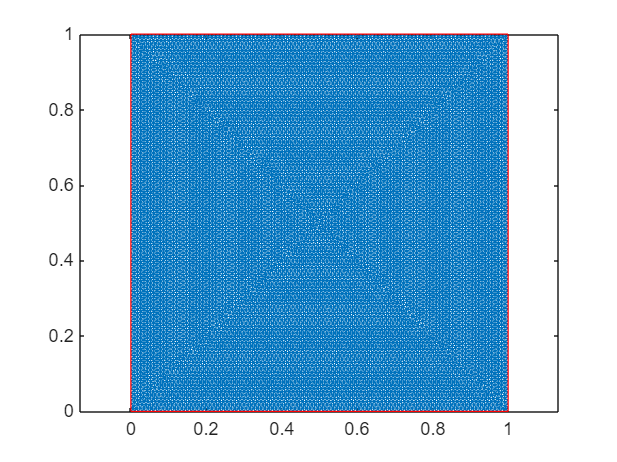

hmax = 0.01;  % a target value for the longest MESH edge length 

generateMesh(model,"Hmax",hmax,"GeometricOrder","linear");

figure
    pdeplot(model)

## Calculate the Solution

Use the [`solve`](matlab:  web(fullfile(docroot, 'pde/ug/pde.thermalmodel.solve.html'))) function to calculate the solution.

PDE_solution = solvepde(model);

## Visualise the solution

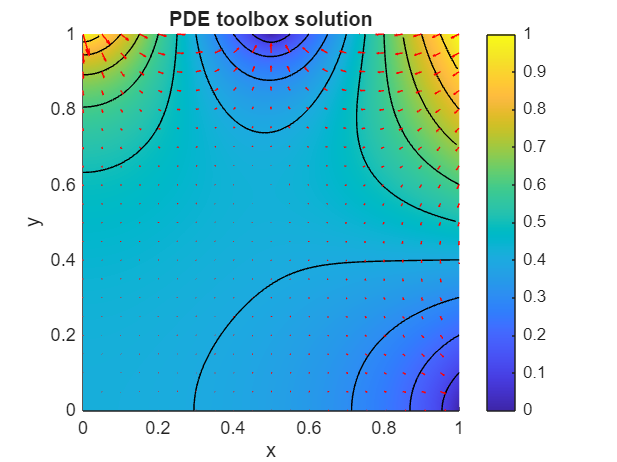

tmp_T_min = min(PDE_solution.NodalSolution);
tmp_T_max = max(PDE_solution.NodalSolution);
PDE_sol_T_contour_levels = linspace(tmp_T_min, tmp_T_max, 11);

figure
    pdeplot(model, FlowData=[-PDE_solution.XGradients, -PDE_solution.YGradients], ...
            XYData=PDE_solution.NodalSolution, colormap='parula', ...
            contour='on', levels=PDE_sol_T_contour_levels)
    axis image
    axis([0,1,0,1])
    xlabel("x")
    ylabel("y")
    title("PDE toolbox solution")

# **Finite Difference approach:**

Now let's solve this exact same problem again .... but using a Finite Difference scheme.  The Finite difference stencil for solving our problem has been derived [**HERE**](matlab:  edit  bh_deriv_for_2d_pde_ellip_heat_ss.mlx) , and for ***internal*** nodes on our plate, the stencil has the form:

-   $T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$     where    $T_{i\;\;,\;j} =T\left(\;x_i \;\;,y_j \;\right)$

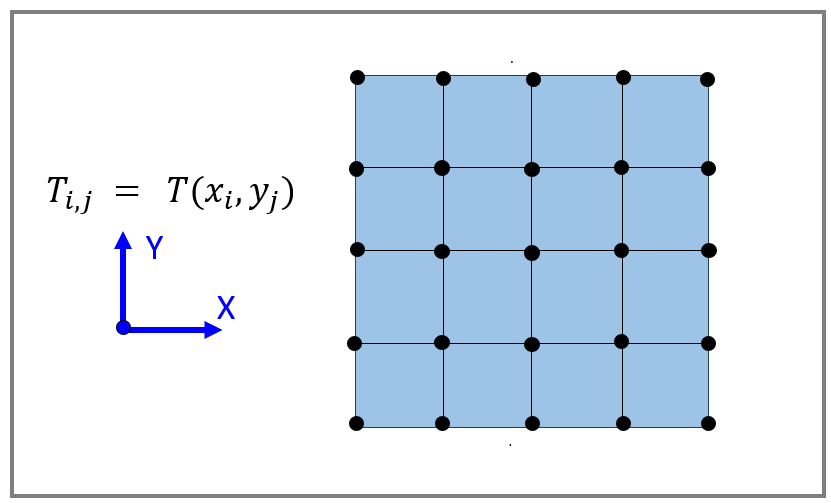

In the Finite Difference approach, we need to write out a stencil equation for ALL nodes in our domain.

- For the INTERNAL nodes we can use the stencil stated above

- For nodes on the plate's BOUNDARY, we'll need to modify this default stencil

Once we've written out the appropriate stencil equation for each node, we'll represent this SYSTEM of equations in matrix form as:

- $A\ldotp x=b$     where    $x$ are the node temperatures

In MATLAB, a problem in the form $A\ldotp x=b$ is solved using the famous "backslash" operator, i.e.:  $x=A\;\;\backslash \;\;b$

## **Define the Grid size**

Slice the square plate into a Grid.  The grid will contain ***n*** intervals in both the X and Y directions

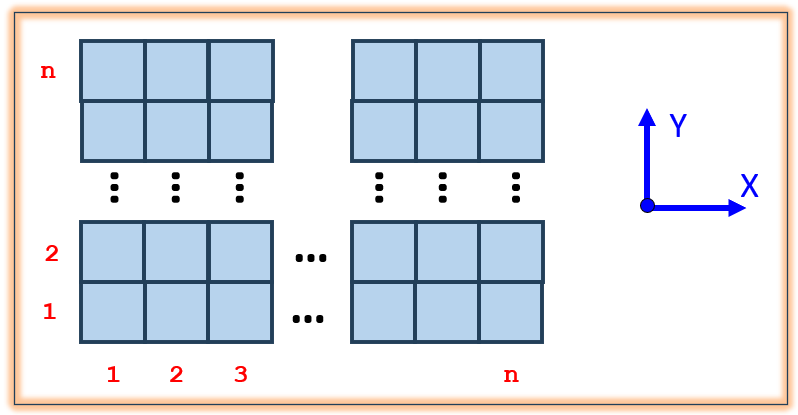

n    = 1*100;           % NUM intervals (same in X, and Y directions)
h    = PLATE_WIDTH/n;   % SPATIAL step  (same in X, and Y directions)

Npt  = n + 1;           % number of points in each of x, y directions
Ndof = Npt*Npt;         % total number of GRID points

### **Define the grid points**

x  = linspace(0, PLATE_WIDTH, Npt); % to generate equally spaced (n + 1) points in x
y  = linspace(0, PLATE_WIDTH, Npt); % to generate equally spaced (n + 1) points in y

So we now have a collection of grid points .... which we'll call **NODES**.  

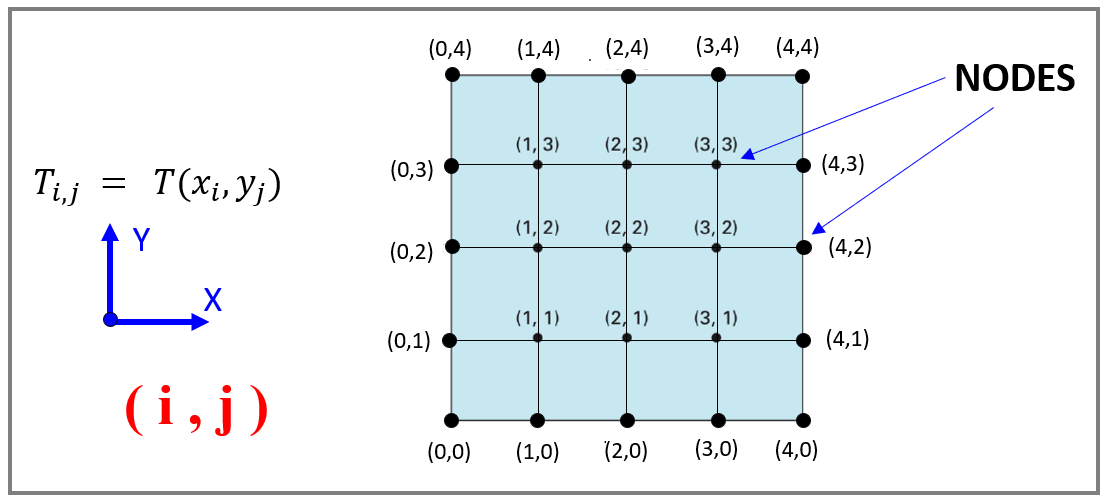

- A NODE has an ID - say $i,j$

- A NODE has Co-ordinates $\left(x_i \;\;\;,\;y_j \right)$

- A NODE has a Temperature  $T_{i\;\;,\;j}$

- Some NODES are BOUNDARY condition nodes 

- Some NODES are INTERNAL nodes 

 For each NODE we can either:

-  write out the Finite Difference stencil      $T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$  (see derivation [**HERE**](matlab:  edit  bh_deriv_for_2d_pde_ellip_heat_ss.mlx)) 

- **OR** we can write out the stencil that incorporates our Boundary Condition

We can then collect/organise these equations in MATRIX form.  The MATRIX form of our system will have the shape: 

-   
$$A\;\ldotp z=\textrm{rhs}$$
 

where:

- 
$$\textrm{transpose}\left(z\right)=\left\lbrack T_{0,0} \;\;T_{1,0} \;\;T_{2,0} \;\;T_{3,0} \;\;T_{4,0} ,\cdots \;\;\;\;\;\;\;T_{0,1} \;\;T_{1,1} \;\;T_{2,1} \;\;T_{3,1} \;\;T_{4,1} ,\cdots \;\;\;\;\;\;T_{0,2} \;\;T_{1,2} \;\;T_{2,2} \;\;T_{3,2} \;\;T_{4,2} ,\cdots \;\;\;\;\;\;\;T_{0,3} \;\;T_{1,3} \;\;T_{2,3} \;\;T_{3,3} \;\;T_{4,3} ,\cdots \;\;\;\;\;\;\;\;\right\rbrack \;$$


Once we have our system MATRICES $A$ and $\textrm{rhs}$, we can then solve for the unknown temperatures via:    $z=A\;\backslash \;\textrm{rhs}$

## Book keeping preparation - using a `dictionary`

Before we attack this problem, let's do a little bit of book keeping - aka setting up some data containers that will make it ***soooo much easier*** to understand how to solve the problem.  Specifcally we will:

- Define a [`dictionary`](matlab:  web(fullfile(docroot, 'matlab/ref/dictionary.html'))) data type to act as our mechanism to **"Look up" information about our NODES  **- dictionaries are VERY FAST at lookup

- Define a [`sparse()`](matlab:  web(fullfile(docroot, 'matlab/ref/sparse.html'))) matrix data type for  efficiently storing our "massive" matrices

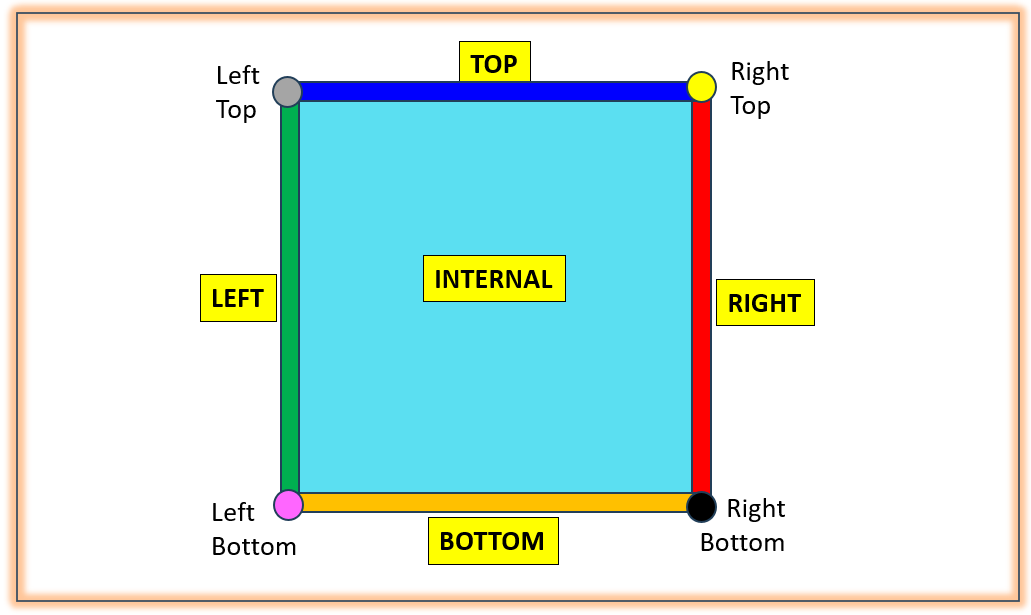

Recall that the Nodes in our grid can be one of 9 different types, where each type corresponds to either an INTERNAL node OR a node with a specific type of boundary condition.  The 9 node types are

- INTERNAL

- BC_RIGHT

- BC_RIGHT_TOP

- BC_RIGHT_BOTTOM

- BC_TOP

- BC_LEFT_TOP

- BC_LEFT

- BC_LEFT_BOTTOM

- BC_BOTTOM

A NODE **Lookup dictionary **will allow us to extract information about a NODE using "plain english" indexing.  For example, 

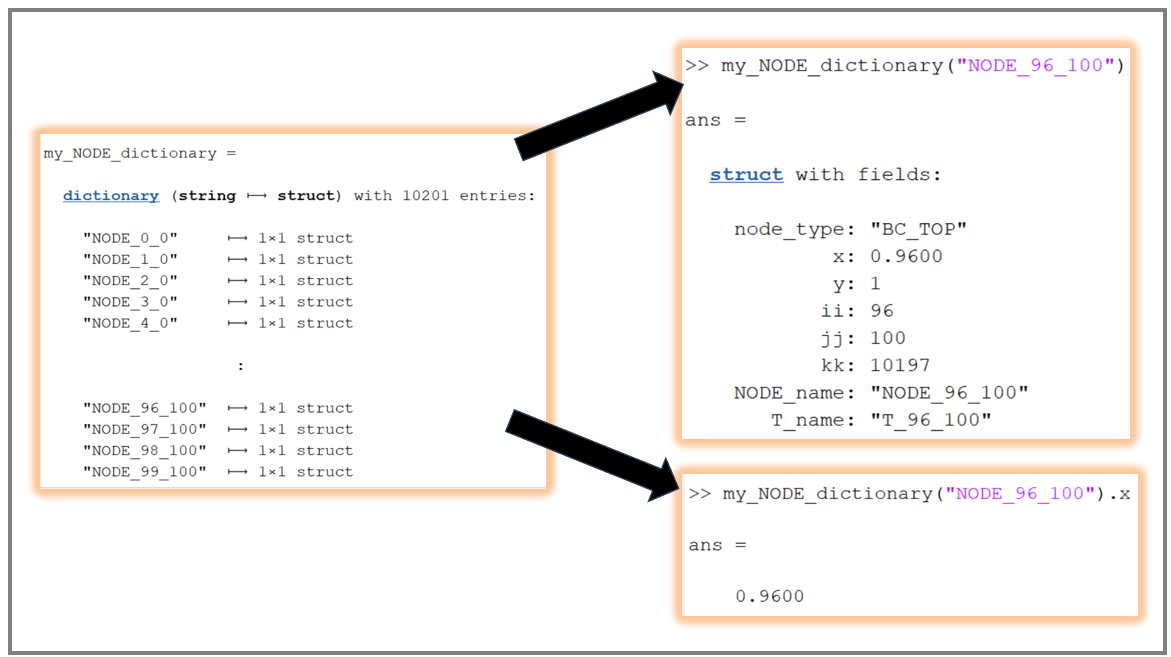

### Create a NODE Lookup DICTIONARY

We'll create the NODE Lookup DICTIONARY via the function [`bh_create_node_lookup()`](matlab:  edit bh_create_node_lookup)`.`  

[NODE_name_list, my_NODE_dictionary] = bh_create_node_lookup(x, y, "mode", "dictionary");

whos my_NODE_dictionary

  Name                    Size               Bytes  Class         Attributes

  my_NODE_dictionary      1x1             21299600  dictionary              



**Using the DICTIONARY :**

Our dictionary is going to be really useful, eg: here's how we'd extract information for NODE_5_7

tmp_data = my_NODE_dictionary("NODE_5_7")

tmp_data = struct with fields:
    node_type: "INTERNAL"
            x: 0.0500
            y: 0.0700
           ii: 5
           jj: 7
           kk: 713
    NODE_name: "NODE_5_7"
       T_name: "T_5_7"


And if you'd like to extract a specific property for the node, use the `".fieldname"` syntax.  For example to extract the `"x"` data, use the syntax

my_NODE_dictionary("NODE_5_7").x

ans = 0.0500

### The List of NODES to process

The other variable returned by the  [`bh_create_node_lookup()`](matlab:  edit bh_create_node_lookup) function is  `NODE_name_list` - this is just a list of NODE labels.  When we assemble our system equation $A\ldotp x=b$, the columns of our $A$ matrix will correspond to the TEMPERATURE co-efficients of the NODES presented in the same order as listed in `NODE_name_list`. i.e.: 

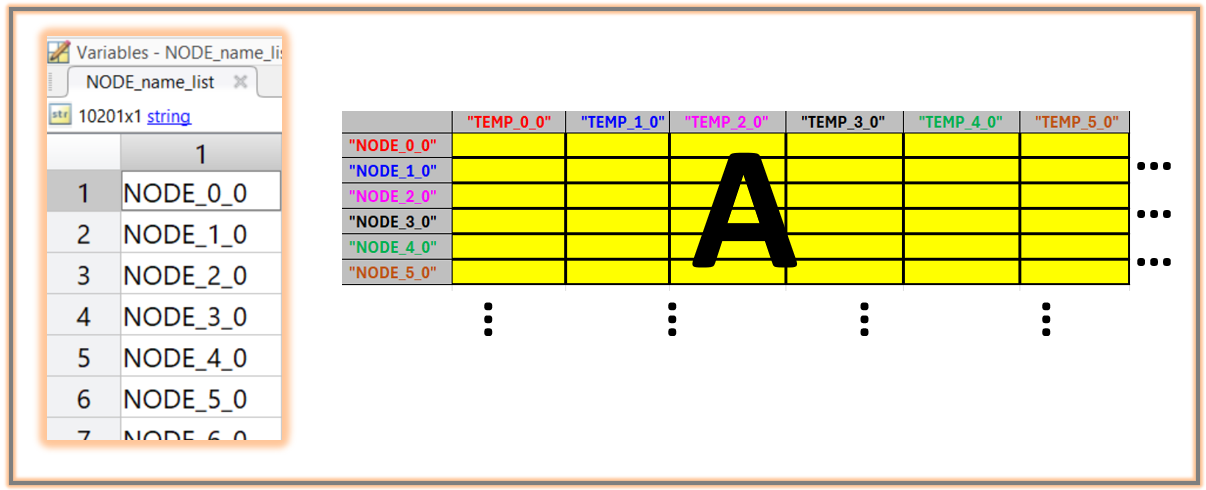

### Create our SPARSE matrix

In just a moment we'll be creating a problem of the form $A\ldotp x=b$ .  So let's preallocate some $A$and $b$ matrices.  The $A$ matrix will be incredibly sparse ... so let's preallocate using the [`sparse()`](matlab:  web(fullfile(docroot, 'matlab/ref/sparse.html'))) function.

- The [`sparse()`](matlab:  web(fullfile(docroot, 'matlab/ref/sparse.html'))) matrix data type allows us to efficiently store "massive" matrices that are mostly populated with ZEROS.

- The syntax :   `S = sparse(m,n)`     generates an `m`-by-`n` all ZERO sparse matrix

- If we tried to use "regular" matrices for these MASSIVE amounts of data .... our laptop would run out of memory.

 A_sys     = sparse(Ndof, Ndof);
 b_sys     = sparse(Ndof, 1);

% OR you could create the SPARSE matrices using SPALLOC - FASTER !!
% A_sys     = spalloc(Ndof, Ndof,  (Ndof*5) );
% b_sys     = spalloc(Ndof, 1, Ndof);

## Pause and Ponder

Let's look at the size of some of these relevant variables

whos NODE_name_list T_name_list  NODE_PROP_LOOKUP_TAB

  Name                    Size             Bytes  Class     Attributes

  NODE_name_list      10201x1             714182  string              




whos A_sys  b_sys    

  Name           Size               Bytes  Class     Attributes

  A_sys      10201x10201            81632  double    sparse    
  b_sys      10201x1                   32  double    sparse    



And also recall the values for our grid size:

Npt    % number of nodes in the X-direction.  

Npt = 101

Ndof   % TOTAL number of nodes in the whole grid

Ndof = 10201


[Npt, Ndof, Npt^2]

ans =          101       10201       10201


## Assemble System of equations

We're now going to assemble a system of equations of the form:

- 
$$A\ldotp x=b$$


So let's process each NODE in our grid and recall that an INTERNAL node has an equation of the form:

-   $T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$     (see derivation [**HERE**](matlab:  edit  bh_deriv_for_2d_pde_ellip_heat_ss.mlx)) 

We'll treat other node types based on the Bounday condition assocaited with each node.

- 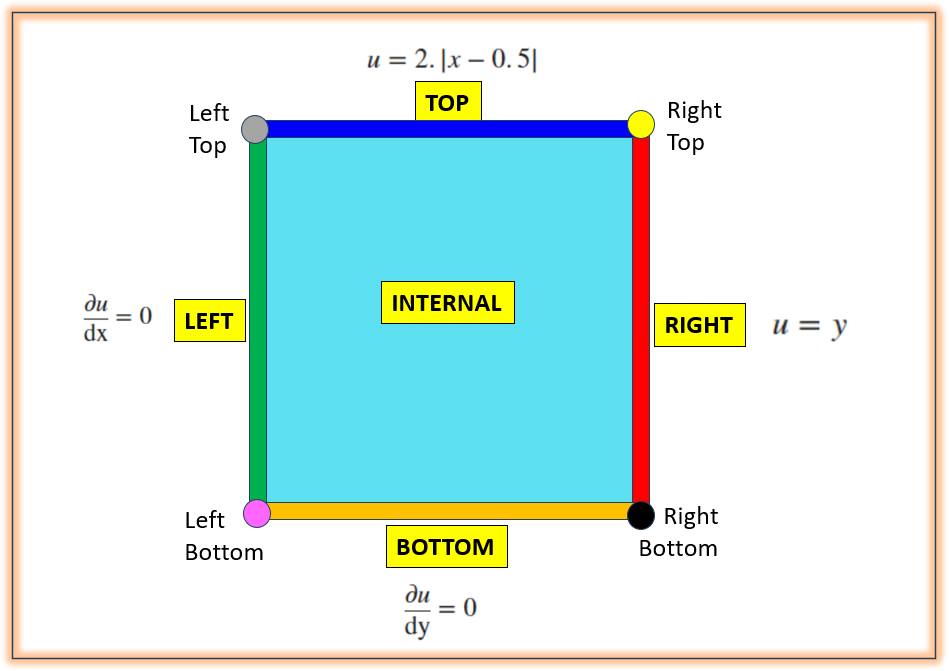

Am curious to see how long this assembly process takes

my_tic = tic;  

### Process each NODE in our grid


for kk=1:length(NODE_name_list)
    % what NODE are we processing
    NODE_ID_str   = NODE_name_list(kk);

    % rip out some properties of this NODE from our DICTIONARY
    NODE_TYPE = my_NODE_dictionary(NODE_ID_str).node_type;
    x_cord    = my_NODE_dictionary(NODE_ID_str).x;
    y_cord    = my_NODE_dictionary(NODE_ID_str).y;    
    ii_ID     = my_NODE_dictionary(NODE_ID_str).ii;
    jj_ID     = my_NODE_dictionary(NODE_ID_str).jj;   


    % PROCESS the node
    switch(NODE_TYPE)  


---> kk=[      1], so 0 % finished 
---> kk=[    510], so 5 % finished 
---> kk=[   1020], so 10 % finished 
---> kk=[   1530], so 15 % finished 
---> kk=[   2040], so 20 % finished 
---> kk=[   2550], so 25 % finished 
---> kk=[   3060], so 30 % finished 
---> kk=[   3570], so 35 % finished 
---> kk=[   4080], so 40 % finished 
---> kk=[   4590], so 45 % finished 
---> kk=[   5100], so 50 % finished 
---> kk=[   5610], so 55 % finished 
---> kk=[   6120], so 60 % finished 
---> kk=[   6630], so 65 % finished 
---> kk=[   7140], so 70 % finished 
---> kk=[   7650], so 75 % finished 
---> kk=[   8160], so 80 % finished 
---> kk=[   8670], so 85 % finished 
---> kk=[   9180], so 90 % finished 
---> kk=[   9690], so 95 % finished 
---> kk=[  10200], so 100 % finished 


If it's an **INTERNAL** node, just use our derived stencil:

- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$$


        case "INTERNAL"    
            % establish where each temperature column is in our A matrix
            ind_1 = my_NODE_dictionary( ("NODE_" + (ii_ID+1) + "_" +  jj_ID)    ).kk;


 ----->  Assembling A and b took : 0.379165 seconds

            ind_2 = my_NODE_dictionary( ("NODE_" + (ii_ID-1) + "_" +  jj_ID)    ).kk;
            ind_3 = my_NODE_dictionary( ("NODE_" +  ii_ID    + "_" + (jj_ID+1)) ).kk;
            ind_4 = my_NODE_dictionary( ("NODE_" +  ii_ID    + "_" + (jj_ID-1)) ).kk;
            ind_5 = my_NODE_dictionary( ("NODE_" +  ii_ID    + "_" +  jj_ID)    ).kk;            


  Name           Size                Bytes  Class     Attributes

  A_sys      10201x10201            881632  double    sparse    
  b_sys      10201x1                  3232  double    sparse    



            % now assign values into our A matrix
            A_sys(kk, ind_1) =  1;
            A_sys(kk, ind_2) =  1;
            A_sys(kk, ind_3) =  1;
            A_sys(kk, ind_4) =  1;
            A_sys(kk, ind_5) = -4;     

Regarding the **RIGHT** edge **Boundary Condition**:

- $T=y\;\;\;\;\Longrightarrow$   Edge **E4 (RIGHT)**

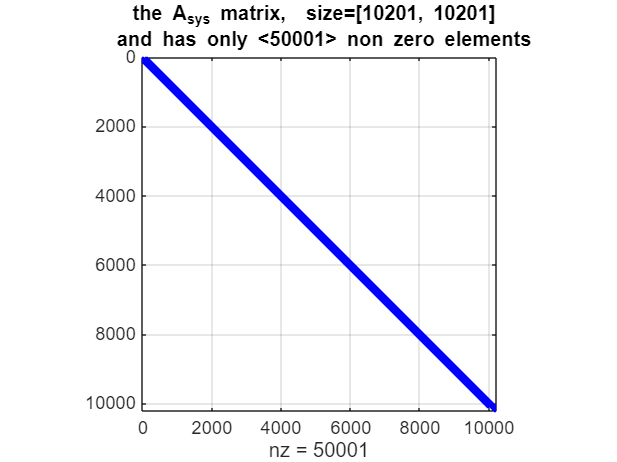

        case {"BC_RIGHT", "BC_RIGHT_TOP", "BC_RIGHT_BOTTOM" }


              ind_1 = my_NODE_dictionary( NODE_ID_str ).kk;

              A_sys(kk, ind_1) =  1;
              b_sys(kk)        =  y_cord;    

Regarding the **TOP** edge **Boundary Condition**:

- $T=2\ldotp \left|x-0\ldotp 5\right|\;\;\;\;\Longrightarrow \;\;\;$Edge **E1 (TOP)**              

        case {"BC_TOP", "BC_LEFT_TOP"}

  Name               Size                Bytes  Class     Attributes

  A_sys          10201x10201            881632  double    sparse    
  T_results      10201x1                163200  double    sparse    
  b_sys          10201x1                  3232  double    sparse    




              ind_1 = my_NODE_dictionary( NODE_ID_str ).kk;

              A_sys(kk, ind_1) =  1;
              b_sys(kk)        =  2*abs(x_cord - 0.5);     

Regarding the **BOTTOM **edge** Boundary Condition **(a NEUMANN BC), we know that for an INTERNAL node we have

- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$$


And the Boundary condition for the BOTTOM edge is:

- $\frac{\partial T}{\partial y}=0$  for $y=0\;\;\;$   

We can represent this boundary condition with a Central Difference approximation:

- 
$$\frac{\partial T}{\partial y}\;=\;0\;=\;\frac{T_{i,j+1} -T_{i,j-1} }{2\ldotp \Delta y}\;\;\;\Longrightarrow \;\;\;\;\;\;T_{i,\;j-1} =T_{i,\;j+1}$$
      

So if we use a  GHOST node in the negative Y direction, ie:  $T_{i,\;j-1} =T_{i,\;j+1}$ our INTERNAL node stencil can be written as

- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;\;\;\;\;\;T_{i,\;j+1} \;\;+\;\;\;\left\lbrace T_{i,\;j-1} \right\rbrace \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=\;0$$


- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;\;\;\;\;\;T_{i,\;j+1} \;\;+\;\;\;\left(T_{i,\;j+1} \;\;\right)\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;\;=\;0$$


- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;2\ldotp T_{i,\;j+1} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=\;\;0$$


        case "BC_BOTTOM"

  Name               Size             Bytes  Class     Attributes

  T_results      10201x1             163200  double    sparse    



            ind_1 = my_NODE_dictionary( ("NODE_" + (ii_ID+1) + "_" +  jj_ID)    ).kk;
            ind_2 = my_NODE_dictionary( ("NODE_" + (ii_ID-1) + "_" +  jj_ID)    ).kk;

Npt = 101

            ind_3 = my_NODE_dictionary( ("NODE_" +  ii_ID    + "_" + (jj_ID+1)) ).kk;
            ind_4 = my_NODE_dictionary( ("NODE_" +  ii_ID    + "_" +  jj_ID)    ).kk;

            A_sys(kk, ind_1) =  1;
            A_sys(kk, ind_2) =  1;
            A_sys(kk, ind_3) =  2;
            A_sys(kk, ind_4) = -4;    

Similarly for our **LEFT **edge** Boundary Condition **(a NEUMANN BC), we know that for an INTERNAL node we have

- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$$


And the Boundary condition for the LEFT edge is:

- $\frac{\partial T}{\partial x}=0$  for $x=0\;\;\;$   

We can represent this boundary condition with a Central Difference approximation:

- 
$$\frac{\partial T}{\partial x}\;=\;0\;=\;\frac{T_{i+1,j} -T_{i-1,j} }{2\ldotp \Delta x}\;\;\;\Longrightarrow \;\;\;\;\;\;T_{i+1,\;j} =T_{i-1,\;j}$$
      

So if we use a  GHOST node in the negative X direction, ie:  $T_{i-1,\;j} =T_{i+1,\;j}$ our INTERNAL node stencil can be written as

- 
$${\;\;\;\;T}_{i+1,\;j} \;\;+\;\;\;\left\lbrace T_{i-1,\;j} \right\rbrace \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=0$$


- 
$${\;\;\;\;T}_{i+1,\;j} \;\;+\;\;\;\left(T_{i+1,\;j} \right)\;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=\;0$$


- 
$$2\ldotp T_{i+1,\;j} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\;\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=0$$


        case "BC_LEFT"

            ind_1 = my_NODE_dictionary( ("NODE_" + (ii_ID+1) + "_" +  jj_ID)     ).kk;

  Name             Size              Bytes  Class     Attributes

  the_T_mat      101x101            164000  double    sparse    
  the_x_mat      101x101             81608  double              
  the_y_mat      101x101             81608  double              



            ind_2 = my_NODE_dictionary( ("NODE_" +  ii_ID    + "_" + (jj_ID+1))  ).kk;
            ind_3 = my_NODE_dictionary( ("NODE_" +  ii_ID    + "_" + (jj_ID-1))  ).kk;
            ind_4 = my_NODE_dictionary( ("NODE_" +  ii_ID    + "_" +  jj_ID)     ).kk;

            A_sys(kk, ind_1) =  2;
            A_sys(kk, ind_2) =  1;
            A_sys(kk, ind_3) =  1;
            A_sys(kk, ind_4) = -4;                 

And lastly take care of the **LEFT, BOTTOM** node - this shares our 2 NEUMANN boundary conditions

Recall that using a Central Difference approximation we can write:

-      $\frac{\partial T}{\partial x}\;=\;0\;=\;\frac{T_{i+1,j} -T_{i-1,j} }{2\ldotp \Delta x}\;\;\;\Longrightarrow \;\;\;\;\;\;T_{i+1,\;j} =T_{i-1,\;j}$     AND

-      
$$\frac{\partial T}{\partial y}\;=\;0\;=\;\frac{T_{i,j+1} -T_{i,j-1} }{2\ldotp \Delta y}\;\;\;\Longrightarrow \;\;\;\;\;\;T_{i,\;j+1} =T_{i,\;j-1}$$


So if we use  GHOST nodes in the negative X and Y direction, ie:  $T_{i-1,\;j} =T_{i+1,\;j}$ our INTERNAL node stencil can be written as

- 
$${\;\;\;\;T}_{i+1,\;j} \;\;+\;\;\;\left\lbrace T_{i-1,\;j} \right\rbrace \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\left\lbrace T_{i,\;j-1} \right\rbrace \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=0$$


- 
$${\;\;\;\;T}_{i+1,\;j} \;\;+\;\;\;\left\lbrace T_{i+1,\;j} \right\rbrace \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\left\lbrace T_{i,\;j+1} \right\rbrace \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=0$$


- 
$${\;\;\;\;2\ldotp T}_{i+1,\;j} \;\;+\;\;{\;\;\;\;2\ldotp T}_{i,\;j+1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=0$$


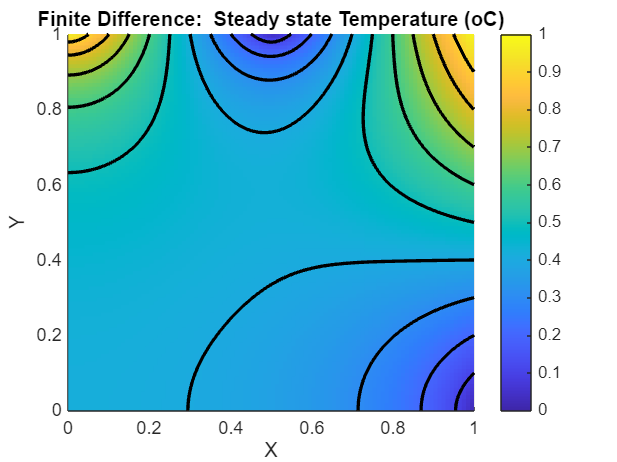

        case "BC_LEFT_BOTTOM"

            ind_1 = my_NODE_dictionary( ("NODE_" + (ii_ID+1) + "_" +  jj_ID)     ).kk;
            ind_2 = my_NODE_dictionary( ("NODE_" +  ii_ID    + "_" + (jj_ID+1))  ).kk;
            ind_3 = my_NODE_dictionary( ("NODE_" +  ii_ID    + "_" +  jj_ID)     ).kk;

            A_sys(kk, ind_1) =  2;
            A_sys(kk, ind_2) =  2;

            A_sys(kk, ind_3) = -4;            
        otherwise
            error("###_ERROR:  Bad !")
    end % switch
        
    % echo some progress stats
    tmp_N_value = round( length(NODE_name_list)/20  );
    if(0==mod(kk,tmp_N_value) || (kk==1) )
        fprintf("---> kk=[%7d], so %d %s finished \n", ...
              kk, round(100*kk/length(NODE_name_list)), "%");
    end

end % for


my_toc = toc(my_tic);

fprintf("\n ----->  Assembling A and b took : %f seconds", my_toc);

## Have a look at our A matrix

So our GLOBAL system $A$ and $b$ matrices have now been populated.

 How big are they ?

whos A_sys  b_sys

**NOTE**:  because we created these matrices as **SPARSE** matrices, they do NOT consume much memory on your laptop.  Have a look at exactly how "sparse" our `A_sys` matrix really is - the BLUE dots correspond to positions storing NON zero values ... and WHITE represents locations where a ZERO would be

figure;
    spy(A_sys, '.b');
        tmp_str = sprintf("the A_{sys} matrix,  size=[%d, %d] \n and has only <%d> non zero elements", ...
                          size(A_sys,1), size(A_sys,2), nnz(A_sys) );
        title(tmp_str);
        grid("on")

## Solve the system `A.x=b` equations

OK, now we can solve our GLOBAL system of equations, ie:  $A\ldotp x=b\;\;\;\;\;\Longrightarrow \;\;\;\;\;x=A\backslash b$ . 

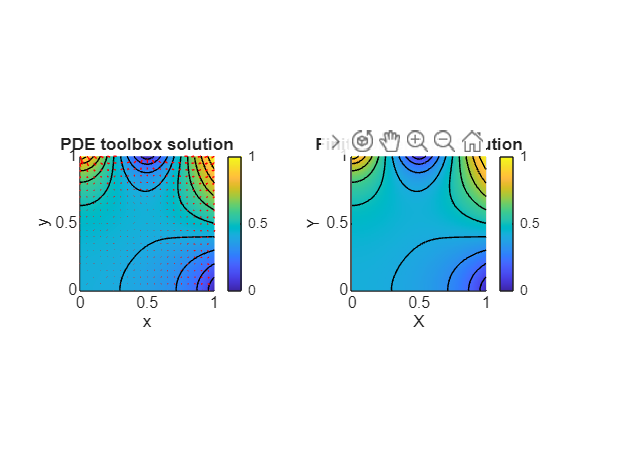

T_results = A_sys \ b_sys;


whos A_sys  b_sys   T_results

## Visualize the solution

Regarding our solution array `T_results` ,  REMEMBER that the  array contains the values:

-  $\left(\mathit{\mathbf{j}}=0,\;\;i=0\longrightarrow N\right)$           $\left(\mathit{\mathbf{j}}=1,\;\;i=0\longrightarrow N\right)$         $\left(\mathit{\mathbf{j}}=2,\;\;i=0\longrightarrow N\right)$         $\left(\mathit{\mathbf{j}}=3,\;\;i=0\longrightarrow N\right)$  ... etc

- 
$$\left\lbrack T_{0,0} \;\;T_{1,0} \;\;T_{2,0} \;\;T_{3,0} \;\;T_{4,0} \cdots \;\;\;\;\;\;\;T_{0,1} \;\;T_{1,1} \;\;T_{2,1} \;\;T_{3,1} \;\;T_{4,1} \cdots \;\;\;\;\;\;T_{0,2} \;\;T_{1,2} \;\;T_{2,2} \;\;T_{3,2} \;\;T_{4,2} \cdots \;\;\;\;\;\;\;T_{0,3} \;\;T_{1,3} \;\;T_{2,3} \;\;T_{3,3} \;\;T_{4,3} \cdots \;\;\;\;\;\;\;\;T_{0,4} \;\;T_{1,4} \;\;T_{2,4} \;\;T_{3,4} \;\;T_{4,4} \cdots \right\rbrack$$


- where:   $T_{i\;\;,\;j} \;=T\left(x_i \;,y_j \right)$

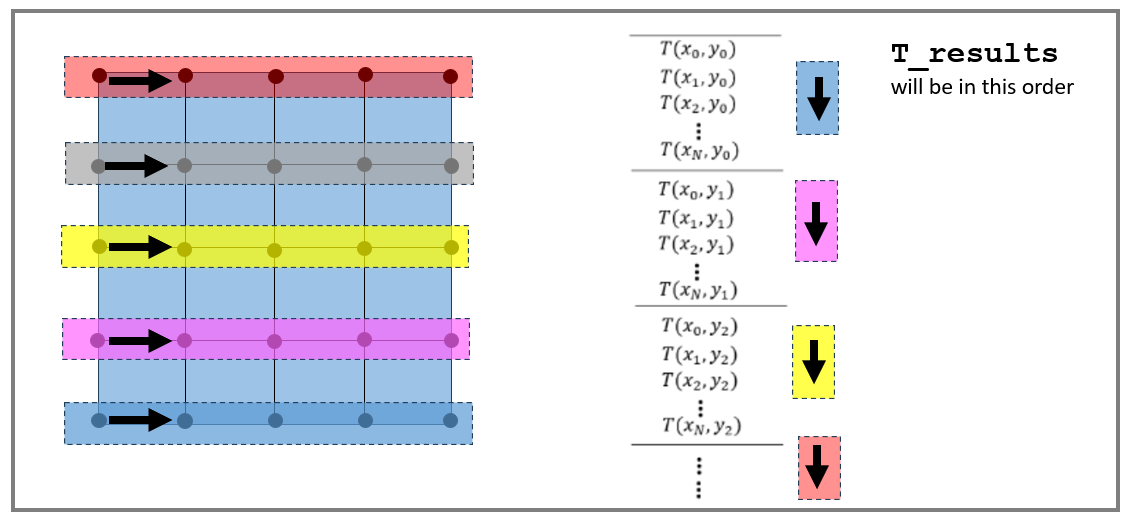

First recall the size

whos  T_results       

 and values of some relevant variables:

Npt

### Reshape our solution vector

Let's view our data as a SURFACE.  

To do this we need to "shape" our Temperature data array `T_results`, into a MATRIX that is arranged as shown below: (see the DOC on the [`surf()`](matlab:  doc surf) and [`meshgrid()`](matlab: doc meshgrid) functions.)

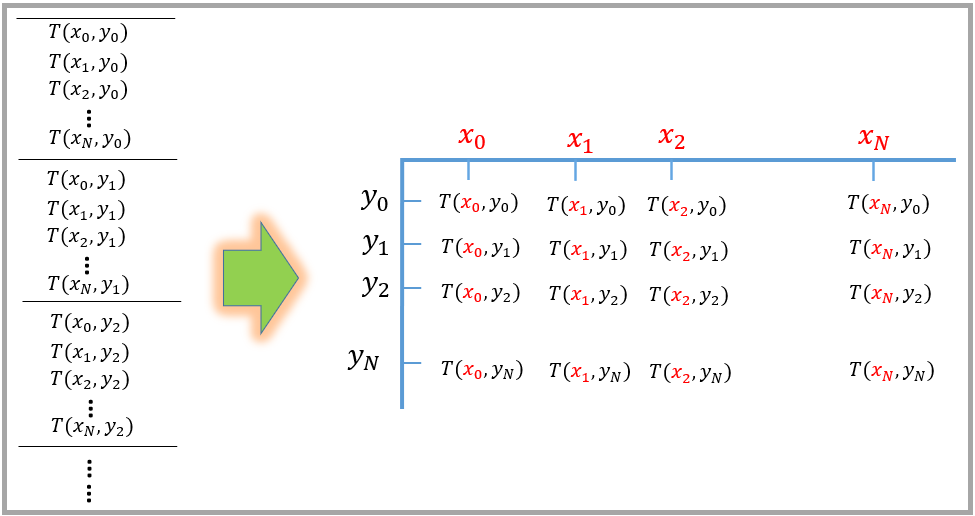

[the_x_mat, the_y_mat] = meshgrid(x, y);

the_T_mat = reshape(T_results, Npt, []);
the_T_mat = the_T_mat';

whos the_x_mat  the_y_mat  the_T_mat

## Plot the Solution as a surface and add contour lines

Let's view our data as a CONTOUR plot - see DOC [`contour`](matlab: doc contour) and [`contour3`](matlab: doc contour3)

We'll overlay contour lines at the same levels as those plotted with the PDE toolbox solution

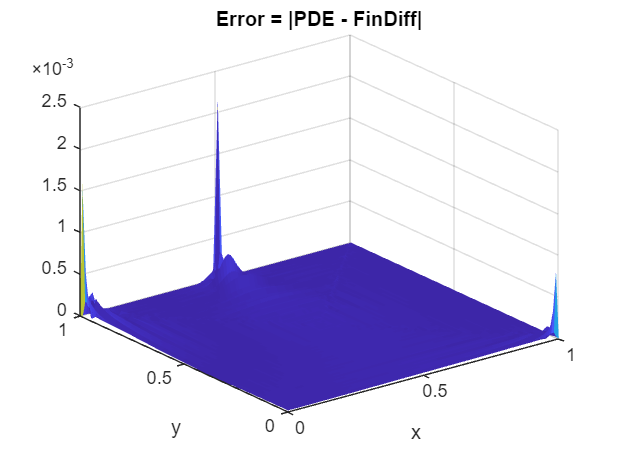

THE_C_LEVELS = PDE_sol_T_contour_levels;

Now plot the Finite Difference solution

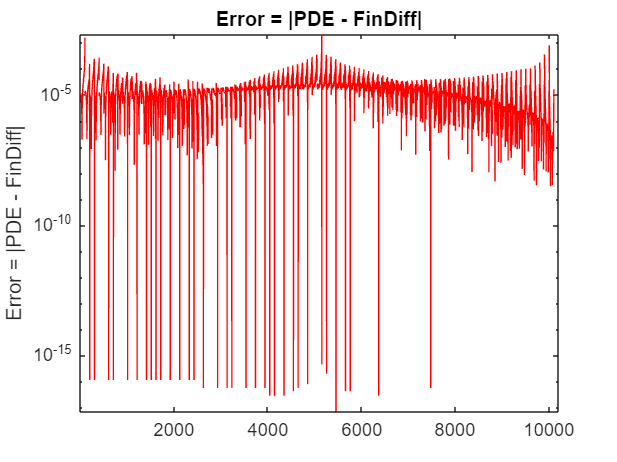

figure;
    surf(the_x_mat, the_y_mat, the_T_mat, "EdgeColor","none"); %, "FaceAlpha",0.7);
       hold("on")
    [~, c_props] = contour3(the_x_mat, the_y_mat, the_T_mat, THE_C_LEVELS,'-k');
        c_props.LineWidth = 2;


            xlabel("X");  ylabel("Y");  zlabel("Temperature (oC)"); 
            colorbar
            colormap(parula)
            view(2)
            title('Finite Difference:  Steady state Temperature (oC)')

# Compare the PDE toolbox solution and our Finite Difference Solution

Let's visually compare the results produced by the** PDE toolbox** against the results produced by our **Finite Difference** approach

figure
    subplot(1,2,1)
        pdeplot(model, FlowData=[-PDE_solution.XGradients, -PDE_solution.YGradients], ...
                       XYData=PDE_solution.NodalSolution, colormap='parula', ...
                       contour='on', levels=PDE_sol_T_contour_levels)
        axis image
        axis([0,1,0,1])
        xlabel("x")
        ylabel("y")
        title("PDE toolbox solution")     

    subplot(1,2,2)
        surf(the_x_mat, the_y_mat, the_T_mat, "EdgeColor","none"); %, "FaceAlpha",0.7);
           hold("on")
        [~, c_props] = contour3(the_x_mat, the_y_mat, the_T_mat, PDE_sol_T_contour_levels,'-k');
            c_props.LineWidth = 0.5;
            xlabel("X");  
            ylabel("Y");  
            colorbar
            colormap(parula)
            view(2)  % birds eye view looking down on surface
            axis equal
            title('Finite Difference Solution')   

Besides "visually" comparing the 2 solutions we can interpolate the PDE toolbox sultion at the NODE points used by our Finite Difference solution ... and then explore the difference between these 2 results

- See the DOC page [`interpolateSolution()`](matlab:  web(fullfile(docroot, 'pde/ug/pde.stationaryresults.interpolatesolution.html')))

T_pde_interp = interpolateSolution(PDE_solution, the_x_mat, the_y_mat);      
T_pde_interp = reshape(T_pde_interp, size(the_T_mat));

T_error = abs(T_pde_interp - the_T_mat);

figure;
   surf(the_x_mat, the_y_mat, T_error, "EdgeColor","none"); %, "FaceAlpha",0.7);
        xlabel("x")
        ylabel("y")
        title("Error = |PDE - FinDiff|") 

And let's flatten this error matrix and plot it on a LOG scale

figure;
    semilogy(T_error(:), "-r");
        ylabel("Error = |PDE - FinDiff|") 
        title("Error = |PDE - FinDiff|") 
        axis tight


Copyright 2024 The MathWorks®, Inc.